**Compute the estimations of the robot**

clear;
close all;

trajectory = readtable('lab4_dataset_traj.csv');
landmarks = readtable('lab4_dataset_landmarks.csv');
odometry = readtable('lab4_dataset_odometry.csv');
sensors = readtable('lab4_dataset_sensors.csv');

% 100 particles
tic
robot_100 = ComputeParticleFilter(100, landmarks, odometry, sensors);
toc

Elapsed time is 1.424194 seconds.



% 500 particles
tic
robot_500 = ComputeParticleFilter(500, landmarks, odometry, sensors);
toc

Elapsed time is 1.520810 seconds.



% 1000 particles
tic
robot_1000 = ComputeParticleFilter(1000, landmarks, odometry, sensors);
toc

Elapsed time is 1.789023 seconds.



% 3000 particles
tic
robot_3000 = ComputeParticleFilter(3000, landmarks, odometry, sensors);
toc

Elapsed time is 2.507152 seconds.


**Plot Estimations of the robot**

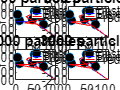

figure;
subplot(2, 2, 1);
plot(landmarks.xL, landmarks.yL, 'o', 'MarkerFaceColor', 'black');
hold on;
plot(trajectory.x, trajectory.y, 'blue');
hold on;
plot(robot_100(:, 1), robot_100(:, 2), 'red');
legend('Obstacles', 'Trajectory', 'Predicted');
title('100 particles');
xlabel('X');
ylabel('Y');
hold off;

subplot(2, 2, 2);
plot(landmarks.xL, landmarks.yL, 'o', 'MarkerFaceColor', 'black');
hold on;
plot(trajectory.x, trajectory.y, 'blue');
hold on;
plot(robot_500(:, 1), robot_500(:, 2), 'red');
legend('Obstacles', 'Trajectory', 'Predicted');
title('500 particles');
xlabel('X');
ylabel('Y');
hold off;

subplot(2, 2, 3);
plot(landmarks.xL, landmarks.yL, 'o', 'MarkerFaceColor', 'black');
hold on;
plot(trajectory.x, trajectory.y, 'blue');
hold on;
plot(robot_1000(:, 1), robot_1000(:, 2), 'red');
legend('Obstacles', 'Trajectory', 'Predicted');
title('1000 particles');
xlabel('X');
ylabel('Y');
hold off;

subplot(2, 2, 4);
plot(landmarks.xL, landmarks.yL, 'o', 'MarkerFaceColor', 'black');
hold on;
plot(trajectory.x, trajectory.y, 'blue');
hold on;
plot(robot_3000(:, 1), robot_3000(:, 2), 'red');
legend('Obstacles', 'Trajectory', 'Predicted');
title('3000 particles');
xlabel('X');
ylabel('Y');
hold off;

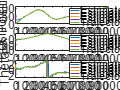


% Plot difference in poses
figure;
% x position
subplot(3, 1, 1);
title('X position');
plot(robot_100(:, 1));
hold on;
plot(robot_500(:, 1));
hold on;
plot(robot_1000(:, 1));
hold on;
plot(robot_3000(:, 1));
hold on;
plot(trajectory.x);
hold off;
legend('Estimated 100 particles', 'Estimated 500 particles', 'Estimated 1000 particles', 'Estimated 3000 particles', 'Trajectory');
xlabel('t');
ylabel('X Position')
% y position
subplot(3, 1, 2);
title('Y position');
plot(robot_100(:, 2));
hold on;
plot(robot_500(:, 2));
hold on;
plot(robot_1000(:, 2));
hold on;
plot(robot_3000(:, 2));
hold on;
plot(trajectory.y);
legend('Estimated 100 particles', 'Estimated 500 particles', 'Estimated 1000 particles', 'Estimated 3000 particles', 'Trajectory');
hold off;
xlabel('t');
ylabel('Y Position')
% Theta
subplot(3, 1, 3)
plot(robot_100(:, 3));
hold on;
plot(robot_500(:, 3));
hold on;
plot(robot_1000(:, 3));
hold on;
plot(robot_3000(:, 3));
hold on;
plot(wrapToPi(trajectory.theta));
legend('Estimated 100 particles', 'Estimated 500 particles', 'Estimated 1000 particles', 'Estimated 3000 particles', 'Trajectory');
hold off;
xlabel('t');
ylabel('Theta');

**Particle Filter Function**

function robot = ComputeParticleFilter(in_num_particles, in_landmarks, in_odometry, in_sensors)
    % Initialize particles
    particles = zeros(in_num_particles, 3);  
    weights = ones(in_num_particles, 1) ./ in_num_particles;

    % Define the uniform distributions for each dimension
    dist_x = makedist('Uniform', 'lower', 0, 'upper', 120);
    dist_y = makedist('Uniform', 'lower', -250, 'upper', 150);
    dist_theta = makedist('Uniform', 'lower', -pi, 'upper', pi);
    for i = 1:in_num_particles
        % Sample from the distributions to initialize particles
        particles(i, 1) = dist_x.random;
        particles(i, 2) = dist_y.random;
        particles(i, 3) = wrapToPi(dist_theta.random);
    end

    % 1. Estimate initial robot pose based on uniformally randomly
    % distributed initial particles.
    robot = zeros(1000, 3);
    weights = PFNormalizeWeights(weights);
    robot(1, :) = PFEstimateRobotPose(particles, weights);
    robot(1, 3) = wrapToPi(robot(1, 3));
    particles = PFResample(particles, weights);
    particles(:, 3) = wrapToPi(particles(:, 3));
    
    for i = 2:1000
        particles(:, 3) = wrapToPi(particles(:, 3));
        % 2. Predict
        particles = PFPredict(i, 0.1, particles, in_odometry);
        particles(:, 3) = wrapToPi(particles(:, 3));
        % 3. Update weights
        weights = PFUpdateWeights(i, particles, in_landmarks, in_sensors);
    
        % 4. Normalize weights
        weights = PFNormalizeWeights(weights);
    
        % 5. Estimate position
        robot(i, :) = PFEstimateRobotPose(particles, weights);
        robot(i, 3) = wrapToPi(robot(i, 3));
    
        % 6. Resample the best particles
        particles = PFResample(particles, weights);
        particles(:, 3) = wrapToPi(particles(:, 3));
    end
end

**Estimate Robot Pose**

function out_pose = PFEstimateRobotPose(in_particles, in_weights)
    ay = sum(in_weights(:) .* sin(in_particles(:, 3)));
    ax = sum(in_weights(:) .* cos(in_particles(:, 3)));
    x = sum(in_particles(:, 1) .* in_weights(:));
    y = sum(in_particles(:, 2) .* in_weights(:));
    out_pose = [x; y; wrapToPi(atan2(ay, ax))];
end

**Prediction**

function out_particles = PFPredict(in_k, in_l, in_particles, in_odometry)
    [num_particles, ~] = size(in_particles);
    out_particles = zeros(size(in_particles));

    % Calculate motion increments relative to the robot's pose
    deltaSR = in_odometry.DeltaSR(in_k);
    deltaSL = in_odometry.DeltaSL(in_k);
    dtheta = wrapToPi((deltaSR - deltaSL) / in_l);
    dxy = ((deltaSR + deltaSL) * 0.5);

    % Calculate distribution 
    mu = 30 * (pi / 180);
    scale = 45 * (pi / 180);
    rd = random('uniform', -1, 3, [num_particles, 1]);
    rt = random('logistic', mu, scale, [num_particles, 1]);

    % Update each particle's pose based on the noisy motion increments and the robot's pose
    out_particles(:, 1) = in_particles(:, 1) + (dxy + rd) .* cos(in_particles(:, 3));
    out_particles(:, 2) = in_particles(:, 2) + (dxy + rd) .* sin(in_particles(:, 3));
    out_particles(:, 3) = wrapToPi(in_particles(:, 3) + (dtheta + rt));
end


**Normalize weights**

function weights = PFNormalizeWeights(in_weights)
    weights = in_weights ./ sum(in_weights);
end

**Update weights**

function weights = PFUpdateWeights(in_k, in_particles, in_landmarks, in_sensors)
    % Get actual measurements from the sensors.
    % 1 x 12 matrix sorted by distances first and then angles.
    actual_distances = [in_sensors.r1(in_k), in_sensors.r2(in_k), in_sensors.r3(in_k), in_sensors.r4(in_k), in_sensors.r5(in_k), in_sensors.r6(in_k)];
    actual_angles    = [in_sensors.th1(in_k), in_sensors.th2(in_k), in_sensors.th3(in_k), in_sensors.th4(in_k), in_sensors.th5(in_k), in_sensors.th6(in_k)];
    actual_measurements = [actual_distances actual_angles];

    % Calculate predicted measurements according to the measurement model,
    % where the matrices are Nx6 where N = #particles in order to match the
    % matrix of actual measurements.
    differences_x = [
        in_landmarks.xL(1) - in_particles(:, 1)...
        in_landmarks.xL(2) - in_particles(:, 1)...
        in_landmarks.xL(3) - in_particles(:, 1)...
        in_landmarks.xL(4) - in_particles(:, 1)...
        in_landmarks.xL(5) - in_particles(:, 1)...
        in_landmarks.xL(6) - in_particles(:, 1)...
    ];
    differences_y = [
        in_landmarks.yL(1) - in_particles(:, 2)...
        in_landmarks.yL(2) - in_particles(:, 2)...
        in_landmarks.yL(3) - in_particles(:, 2)...
        in_landmarks.yL(4) - in_particles(:, 2)...
        in_landmarks.yL(5) - in_particles(:, 2)...
        in_landmarks.yL(6) - in_particles(:, 2)...
    ];
    predicted_distances = sqrt(differences_x.^2 + differences_y.^2);
    predicted_angles = wrapToPi(atan2(differences_y(:, :), differences_x(:, :))) - in_particles(:, 3);
    predicted_measurements = [predicted_distances wrapToPi(predicted_angles)];

    % Calculate differences between actual and predicted.
    differences = predicted_measurements - actual_measurements;
    differences(:, 7:12) = wrapToPi(differences(:, 7:12));
    
    % Calculate logistic probability distribution of the weights of the
    % particles. pdf is Nx12, where N = #particles due to
    sd = 1;
    sb = 20 * (pi/180);
    pdf_distances = pdf('logistic', differences(:, 1:6), 0, sd);
    pdf_angles = pdf('logistic', differences(:, 7:12), 0, sb);

    % Multiply all the columns of each row to get the weights for the particles.
    weights = prod([pdf_distances wrapToPi(pdf_angles)], 2);
end

function out_particles = PFResample(in_particles, in_weights)
    
    num_particles = size(in_particles, 1);
    out_particles = zeros(size(in_particles));

    % Normalize the weights
    normalized_weights = in_weights ./ sum(in_weights);
    
    % Initialize variables
    r = rand / num_particles;
    c = normalized_weights(1);
    i = 1;

    % Resampling
    for m = 1:num_particles
        U = r + (m - 1) / num_particles;
        while U > c
            i = i + 1;
            c = c + normalized_weights(i);
        end
        out_particles(m, :) = in_particles(i, :);
    end
end